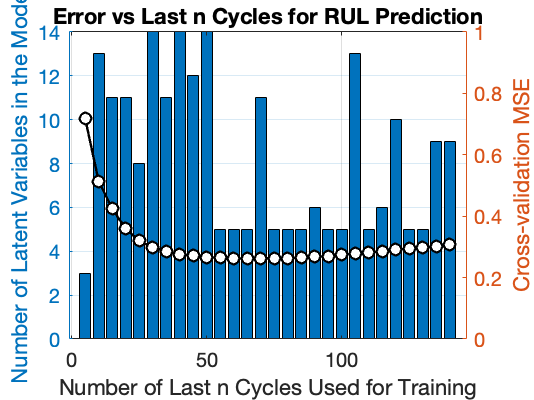

clear; close all; clc

% Define the range of 'n' values (last n cycles) to test
n_values = 5:5:140;
errors = zeros(2, length(n_values));

% Additional sensors to remove (can be empty)
%Optimal models with sensors removed (uncomment for corresponding model)
%remove_additional = [2, 8, 9, 13, 14, 3, 17, 20, 15,7, 21, 12]; % model 1
%remove_additional = [5,6, 7, 12,3, 17,2, 8, 9, 18, 20,10, 13]; % model 2
%remove_additional = [6, 15, 20, 21, 7, 12, 14, 2, 3, 8, 9]; % model 3
%remove_additional = [9, 7, 2, 20, 12, 21, 3, 14, 15, 13]; % model 4
remove_additional = [1];
kFolds = 5;
model_num = 1; % Scenario (dataset)
% Loop through each value of 'n' for error analysis
do_plot = false;  % Set to false to suppress plotting during error analysis
for idx = 1:length(n_values)
    n = n_values(idx);
    [~, errs] = train_model_and_plot(model_num, n, remove_additional(model_num), do_plot, kFolds);
    errors(1, idx) = errs.val;
    errors(2, idx) = errs.vars;
end

% Plot the error as a function of 'n'
figure;
yyaxis right
plot(n_values, errors(1, :), '-ok','LineWidth',1.2,'MarkerFaceColor','auto');
xlabel('Number of Last n Cycles Used for Training');
ylabel('Cross-validation MSE');
ylim([0 1])
yyaxis left
bar(n_values, errors(2, :))
ylabel('Number of Latent Variables in the Model')
title('Error vs Last n Cycles for RUL Prediction');
grid on;


% Choose the optimal number of cycles
[~, optimal_idx] = min(errors(1,:));
optimal_n = n_values(optimal_idx);
%optimal_n = 70; Uncomment if you want to manually change the optimal n
fprintf('Optimal number of n Cycles: %d\n with %d latent variables\n', optimal_n, errors(2,optimal_idx));

Optimal number of n Cycles: 70
 with 11 latent variables


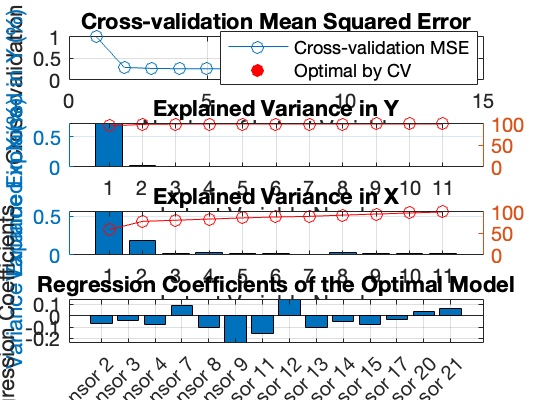

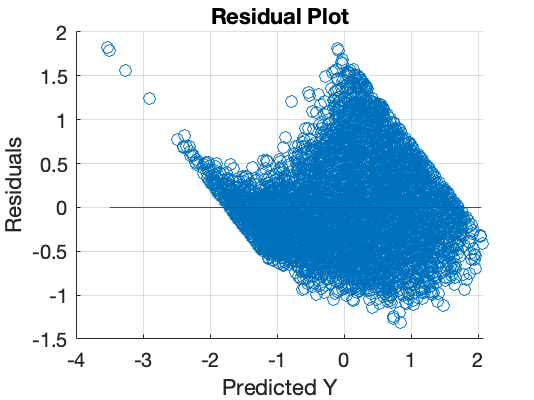

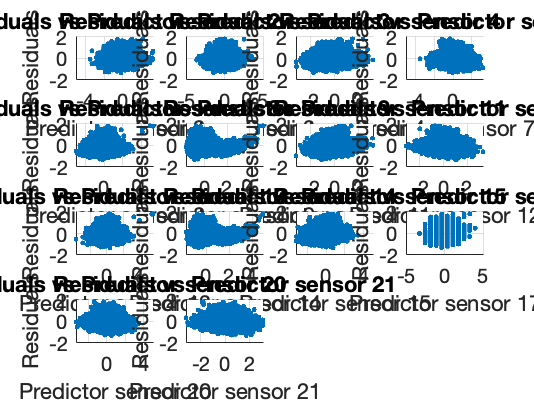

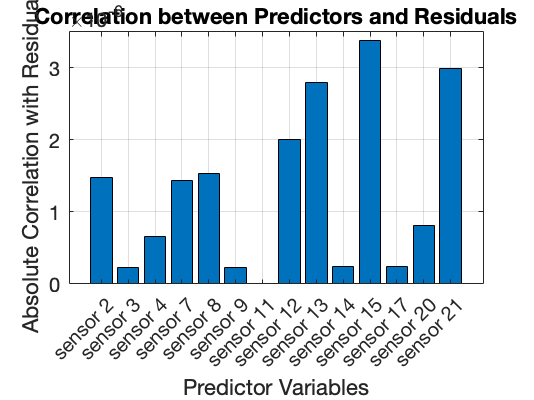

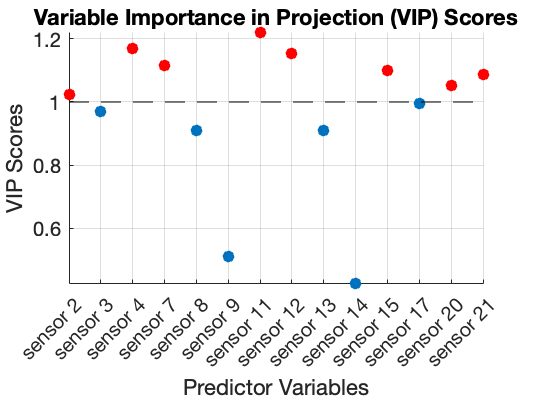


% Perform detailed analysis for the optimal 'n'
do_plot = true;  % Enable plotting for detailed analysis

% Optionally specify the number of latent variables
desired_num_latent_variables = [];  % Set to desired number or leave empty[]
[model, ~] = train_model_and_plot(model_num,optimal_n, remove_additional, do_plot, kFolds, desired_num_latent_variables);

function [model, errors] = train_model_and_plot(model_num, n, remove_additional, do_plot, kFolds, optimal_vars)
    % Extract data
    sce = extract_data(model_num, remove_additional); % models = 1

    % Filter data to keep only the last 'n' cycles before failure for each engine
    last_n_data = filter_last_n_cycles(sce, n);

    % Preprocess model with proper normalization and data preparation
    model = model_preparation(last_n_data, 42);

    % Define the maximum number of latent variables
    max_latent_variables = min(size(model.X_train, 2) - 1, size(model.X_train, 1) - 1);

    % Perform PLS regression with maximum number of latent variables
    [XL_full, YL_full, XS_full, YS_full, B_full, var_full, MSE_full, stats_full] = ...
        plsregress(model.X_train, model.y_train, max_latent_variables, 'CV', kFolds);

    % Calculate errors
    [errors.val, errors.vars] = min(MSE_full(2,:));

    % Determine the number of latent variables to use
    if exist('optimal_vars', 'var') && ~isempty(optimal_vars)
        num_latent_variables = optimal_vars;
    else
        num_latent_variables = errors.vars;
    end

    % Recalculate the model with the specified number of latent variables
    [model.XL, model.YL, model.XS, model.YS, ...
        model.B, model.var, model.MSE, model.stats] = ...
        plsregress(model.X_train, model.y_train, num_latent_variables);

    % Calculate predicted values for training set
    y_pred_train = [ones(size(model.X_train, 1), 1) model.X_train] * model.B;

    % Calculate residuals
    residuals = model.y_train - y_pred_train;

    if do_plot
        % Plot Cross-validation MSE
        figure;
        subplot(4,1,1);
        plot(1:max_latent_variables, MSE_full(2,1:max_latent_variables),'o-')
        hold on
        plot(errors.vars, MSE_full(2,errors.vars),'ro','MarkerFaceColor','r')
        if exist('optimal_vars', 'var') && ~isempty(optimal_vars)
            plot(num_latent_variables, MSE_full(2,num_latent_variables),'gs','MarkerFaceColor','g')
            legend('Cross-validation MSE', 'Optimal by CV', 'User-selected', 'Location', 'Best')
        else
            legend('Cross-validation MSE', 'Optimal by CV', 'Location', 'Best')
        end
        hold off
        title("Cross-validation Mean Squared Error");
        xlabel("Number of Latent Variables");
        ylabel("Cross-validation MSE");
        ylim([0 1])
        grid on

        % Plot Explained Variance in Y
        subplot(4,1,2);
        model.R2 = 100 * cumsum(model.var(2,:))/sum(model.var(2,:));
        yyaxis left
        bar(1:num_latent_variables, model.var(2,:))
        ylabel('Variance Explained in Y (%)')
        yyaxis right
        plot(1:num_latent_variables, model.R2, 'r-o')
        ylim([0 100])
        ylabel('Cumulative Variance Explained (%)')
        title("Explained Variance in Y");
        xlabel("Latent Variable Number");
        grid on

        % Plot Explained Variance in X
        subplot(4,1,3);
        model.varx = 100 * cumsum(model.var(1,:))/sum(model.var(1,:));
        yyaxis left
        bar(1:num_latent_variables, model.var(1,:))
        ylabel('Variance Explained in X (%)')
        yyaxis right
        plot(1:num_latent_variables, model.varx, 'r-o')
        ylim([0 100])
        ylabel('Cumulative Variance Explained (%)')
        title("Explained Variance in X");
        xlabel("Latent Variable Number");
        grid on

        % Plot Regression Coefficients
        subplot(4,1,4);
        bar(model.B(2:end,1));
        xlabel("Predictors");
        ylabel("Regression Coefficients");
        title("Regression Coefficients of the Optimal Model");
        ax = gca;
        ax.XTick = 1:length(model.varNames(1:end-1));
        ax.XTickLabel = model.varNames(1:end-1);
        xtickangle(45);
        grid on

        % Plot Residuals vs Predicted Y
        figure;
        scatter(y_pred_train, residuals);
        hold on;
        plot(y_pred_train, zeros(size(y_pred_train)), 'r--');  % Reference line for 0 residuals
        hold off;
        xlabel('Predicted Y');
        ylabel('Residuals');
        title('Residual Plot');
        grid on

        % Plot Residuals vs Each Predictor
        num_predictors = size(model.X_train, 2);
        figure;
        for j = 1:num_predictors
            subplot(ceil(sqrt(num_predictors)), ceil(sqrt(num_predictors)), j);
            scatter(model.X_train(:, j), residuals, '.');
            xlabel(sprintf('Predictor %s', model.varNames{j}));
            ylabel('Residuals');
            title(sprintf('Residuals vs Predictor %s', model.varNames{j}));
            grid on
        end

        % Calculate Absolute Correlations between Predictors and Residuals
        correlations = zeros(num_predictors, 1);
        for j = 1:num_predictors
            correlations(j) = abs(corr(model.X_train(:, j), residuals));
        end
        % Plot Bar Plot of Correlations
        figure;
        bar(correlations);
        %ylim([0 1]);
        xlabel('Predictor Variables');
        ylabel('Absolute Correlation with Residuals');
        title('Correlation between Predictors and Residuals');
        ax = gca;
        ax.XTick = 1:num_predictors;
        ax.XTickLabel = model.varNames(1:end-1);
        xtickangle(45); % Rotate x-axis labels for readability
        grid on;

        % Calculate VIP Scores
        W0 = model.stats.W ./ sqrt(sum(model.stats.W.^2,1));
        p = size(model.XL,1);
        sumSq = sum(model.XS.^2,1).*sum(model.YS.^2,1);
        vipScore = sqrt(p* sum(sumSq.*(W0.^2),2) ./ sum(sumSq,2));

        indVIP = find(vipScore >= 1);

        % Plot VIP Scores
        figure;
        scatter(1:length(vipScore), vipScore, "filled", 'o')
        hold on
        scatter(indVIP, vipScore(indVIP), "filled", 'ro')
        plot([1 length(vipScore)], [1 1], '--k')
        hold off
        axis tight
        xlabel('Predictor Variables')
        ylabel('VIP Scores')
        title('Variable Importance in Projection (VIP) Scores')
        ax = gca();
        ax.XTick = 1:length(model.varNames(1:end-1));
        ax.XTickLabel = model.varNames(1:end-1);
        xtickangle(45);
        grid on
    end
end




function table_data = extract_data(scenario_number,additional)
    % Extracts each dataset for a given scenario number
    filename = sprintf('trainFD00%d.mat', scenario_number);
    data = load(filename);
    varname = sprintf('trainFD00%d', scenario_number);
    table_data = data.(varname);

    % Define index names
    index_names = {'engine', 'cycle'};
    
    % Define setting names
    setting_names = {'setting_1', 'setting_2', 'setting_3'};
    
    % Sensor names
    sensor_names = cell(1, 21);  % Preallocate a cell array for 21 sensors
    for i = 1:21
        sensor_names{i} = ['sensor ', num2str(i)];
    end
        
    % Concatenate all the names into one cell array
    col_names = [index_names, setting_names, sensor_names];
    table_data.Properties.VariableNames = col_names;

    data = table_data{:, 6:end}; % Sensor data
    std_vals = std(data);
    num_sensors = size(data, 2);
    unique_vals = zeros(1, num_sensors);

    for i = 1:num_sensors
        unique_vals(i) = length(unique(data(:, i)));
    end
    % Remove index if std near 0 or less than 5 unique values and specified
    % sensors in additional array
    if ~isempty(additional)
        sensors_removed = union(union(find(unique_vals < 5), find(std_vals < 1e-5)),additional);
    else
        sensors_removed = union(find(unique_vals < 5), find(std_vals < 1e-5));
    end
    for i = sensors_removed
        table_data = removevars(table_data, sprintf('sensor %d',i));
    end

    table_data = add_RUL_column(table_data);
end

function df = add_RUL_column(df)
    % Group by 'engine' and calculate the maximum 'cycle' for each engine
    [~, ~, unit_indices] = unique(df.engine);
    max_cycles = accumarray(unit_indices, df.cycle, [], @max);

    % Add a 'max_cycle' column to the table
    max_cycles_per_unit = max_cycles(unit_indices);
    df.max_cycle = max_cycles_per_unit;

    % Calculate the Remaining Useful Life (RUL)
    df.RUL = df.max_cycle - df.cycle;

    % Remove the 'max_cycle' column
    df.max_cycle = [];
end

function filtered_data = filter_last_n_cycles(data, n)
    % Filter the dataset to only include the last 'n' cycles before failure for each engine
    unique_engines = unique(data.engine);
    filtered_data = [];

    for engine = unique_engines'
        engine_data = data(data.engine == engine, :);
        last_n_cycles = max(engine_data.cycle) - n + 1;
        engine_last_n = engine_data(engine_data.cycle >= last_n_cycles, :);
        filtered_data = [filtered_data; engine_last_n];
    end
end

function model = model_preparation(df_pre, seed)
    units = unique(df_pre.engine);

    % Create training and testing datasets
    rng(seed); % For reproducibility
    shuffled_units = units(randperm(length(units)));
    split_idx = round(0.8 * length(shuffled_units));

    engines = df_pre.engine;
    df_pre(:, {'cycle', 'engine', 'setting_1', 'setting_2', 'setting_3'}) = [];

    % Split units into training and testing
    train_units = shuffled_units(1:split_idx);
    test_units = shuffled_units(split_idx + 1:end);

    % Extract training data for normalization
    X_train = df_pre(ismember(engines, train_units), 1:end - 1);

    % Compute mean and std from training data only
    model.mu = mean(X_train{:,:});
    model.std = std(X_train{:,:});

    % Normalize training data
    model.X_train = (X_train{:,:} - model.mu) ./ model.std;
    model.y_train = df_pre.RUL(ismember(engines, train_units), :);

    % Extract test data
    X_test = df_pre(ismember(engines, test_units), 1:end - 1);

    % Normalize test data using the training mean and std
    model.X_test = (X_test{:,:} - model.mu) ./ model.std;
    model.y_test = df_pre.RUL(ismember(engines, test_units), :);

    model.varNames = df_pre.Properties.VariableNames;

    % Normalize y_train and y_test using mean and std from y_train
    model.y_mu = mean(model.y_train);
    model.y_std = std(model.y_train);

    % Normalize y values
    model.y_train = (model.y_train - model.y_mu) / model.y_std;
    model.y_test = (model.y_test - model.y_mu) / model.y_std;
end
